# Accesing all colors from SOROTOKI

SOROTOKI has its own color libary accessed through col(int). This will return a [3x1] float array between [0,1] of RBG colors.

A = col()   % prints a matrix of all color set

A =          0    0.3451    0.6588
    0.7922    0.1176    0.1725
    0.2039    0.6549    0.2471
    0.9333    0.4392    0.1373
    0.4941    0.1451    0.5137
    0.9765    0.6706    0.0824
    0.2431    0.1804    0.5255
    0.7137    0.8196    0.1412
    0.3725    0.1647    0.5176
    0.9020    0.2863    0.1569


# Using col(int) 

Let's do a simple `sin(x)` plot

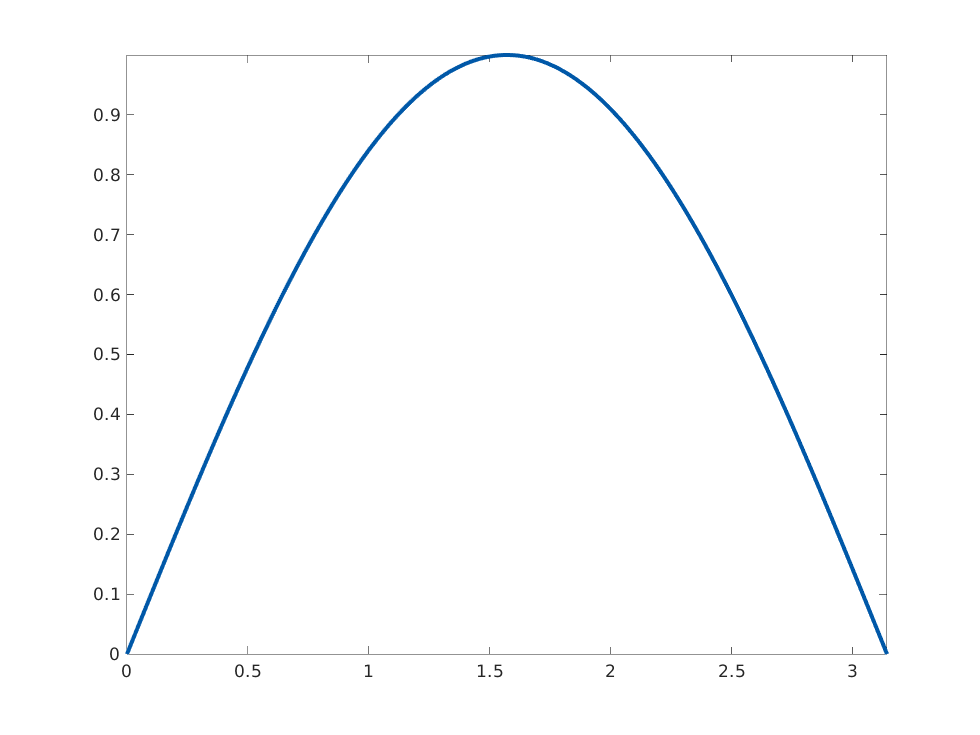

x = linspace(0,pi,500);  % generate field
y = @(x) sin(x);         % generate functional

plot(x,y(x),'Color',col(1),'LineWidth',3); % plot
axis tight;

# All colors

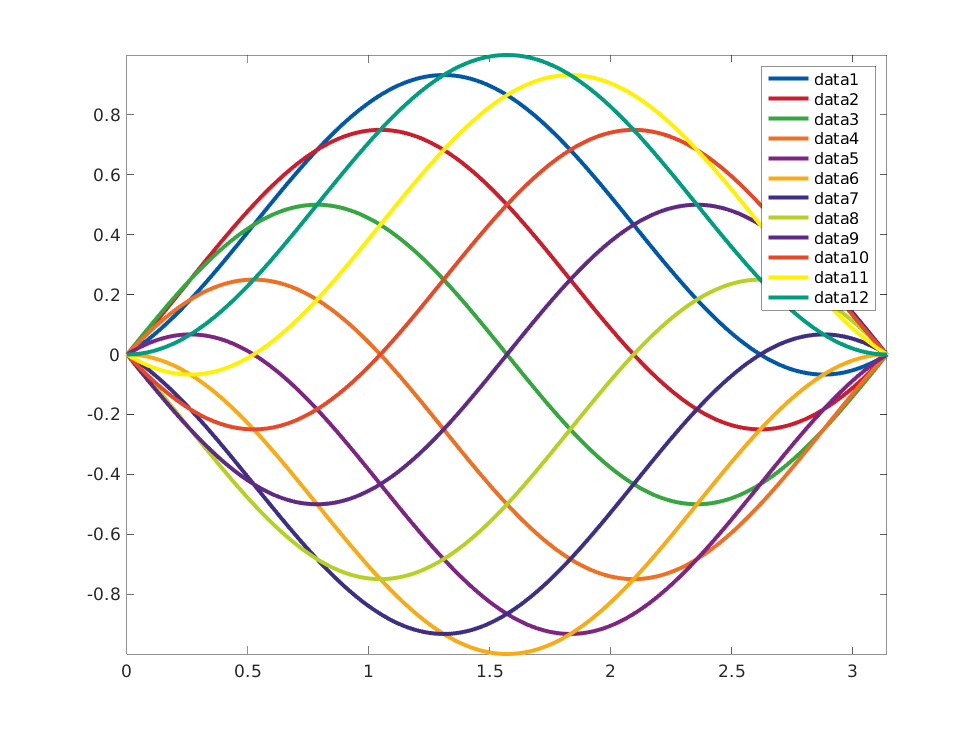

% we can easily use a FOR loop to plot all the colors

N   = size(col(),1); % get size of col() libary
phi = 2*pi/N;        % compute sin offset
W   = sin(x);        % weighting

% loop over all colors
for ii = 1:N
    plot(x,W.*y(x + ii*phi),'Color',col(ii),'LineW',3);
    hold on;
    axis tight;
end

legend;

# Overwriting the color-order from MATLAB

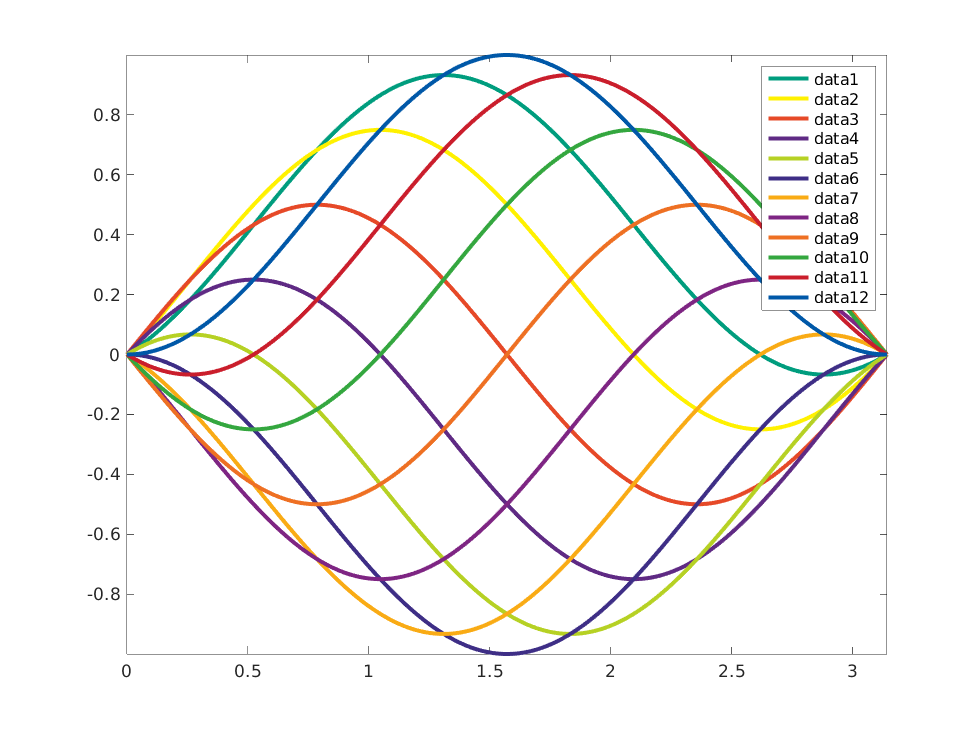

clf;

% loop over all colors
for ii = 1:N
    plot(x,W.*y(x + ii*phi),'LineW',3);
    hold on;
    axis tight;
end

colororder(flipud(col));    % overwrite color order
legend;